# Lecture 7

## Basic terminology

### Parameter vs. Statistic

In statistics, a **parameter** denoted $\theta$ is a numerical value that states something about the entire population. Since a parameter is difficult to obtain, we use a statistic. A **statistic** is a numerical value that states something about a small sample of the entire population. The value of a parameter is a fixed number whereas a statistic can vary because it depends on the given sample. 

### Estimators

An **estimator** denoted $\theta^ˆ$ is a rule or a formula that can approximate some parameter $\theta$ given a sample of $N$ observations.

For example, to estimate the mean value $m$ of a random variable $X$, we can use the arithmetic average as an estimate:

        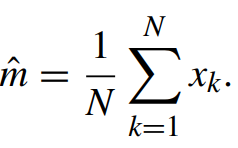

This is called the **sample mean **estimator.

Sample variance

        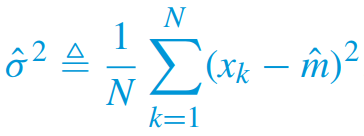

Sample covariance

        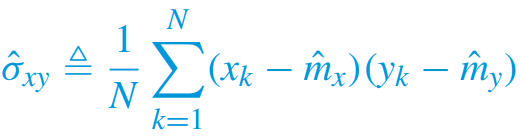

### Estimator Evaluation

The quality of an estimator $\theta^ˆ$ of a parameter $\theta$ is evaluated based on three properties:

- Bias

- Variance

- Mean square error

#### Bias

        

When $B\left(\theta^ˆ \right)=0$ then the estimator yields the correct value on average when used a large number of time. An estimator with $B=0$ is called **unbiased** estimator.

#### Variance

        

The variance describes the spread of the estimates about its expected value.

#### Mean Square Error 

measures the average deviation of the estimator $\theta^ˆ$ from the true value $\theta$:

        

By rewrite Eq. (14.5) we see that the mean square error takes into consideration both the variance and the bias of the estimator:

        

#### Bias-variance tradeoff

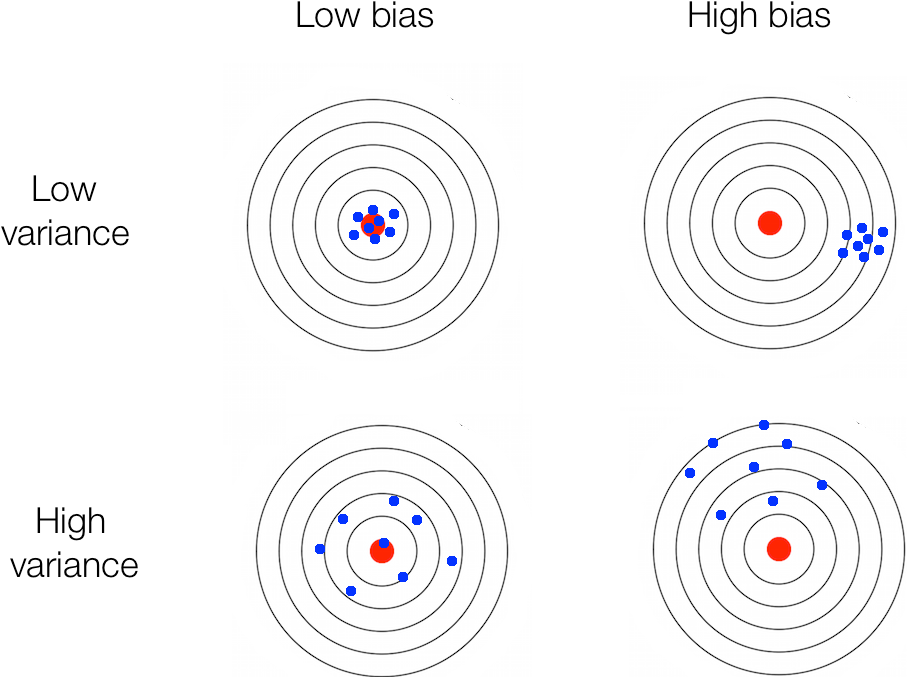

A good estimator should have zero bias and the smallest possible variance. However, typically these two quantities conflict with each other. This is know as the bias-variance tradeoff.

#### Consistency

An estimator is said to be **consistent** if its estimate converges to the true value $\theta$ as the number of observations $N$ approaches infinity.

From Eq. (14.6), we see that if variance and the bias of the estimator is zero then the estimator converges to the true value.

        

Therefore, a sufficient condition for a consistent estimator is that boths its variance and bias converge to zero as the number of observations becomes very large.

## Power Spectrum Estimation

Recall power spectrum is defined as follows:

        
$$S_{\mathrm{xx}} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{xx}} \left(\ell \right)e^{-j\omega \ell }$$


We want to estimate the PSD of a zero-mean wide-sense stationary process.

General approach for power spectrum estimation of a random signal from a finite set of $N$ observations:

1) Window the observed signal $y\left(n\right)$

        
$$y_w \left(n\right)=w\left(n\right)y\left(n\right),\;0\le n\le N-1$$


2) Take the Fourier Transform:

        
$$y_w \left(n\right)\leftrightarrow X_w \left(e^{j\omega } \right)$$


3) Estimate the power spectrum

        $\hat{S_{\mathrm{xx}} } \left(\omega \right)=\frac{1}{N\cdot F}{\left|X_w \left(e^{j\omega } \right)\right|}^2$ where $F$ is constant that depends on the window

### Spectral Leakage

Leakage is an artefact of an FFT applied to a non-periodic data. Even if a signal is periodic like a sinousoid, when the signal is measured with some interval it can be non-periodic. The issue is that FFT  assumes that the signal is periodic and repeats itself after the measured interval. This is not the case when the data is non-periodic, which contains sharp transitions at the end of each measured interval. These sharp changes have a broad frequency response which lead to spectral leakage. Windows can help *minimize* the effects of leakage by smoothing the time domain signal, but cannot eliminate leakage.

A signal with leakage (green in *Figure 2*) has lower amplitude and a broader frequency response than a signal with no leakage (red in *Figure 2*). This makes it difficult to quantify the signal properly in the frequency domain.

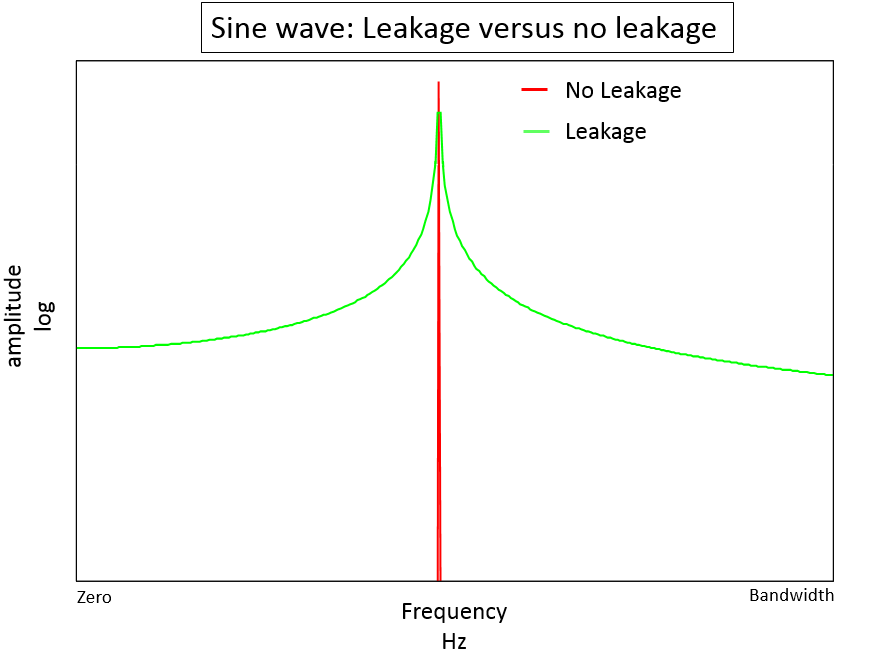

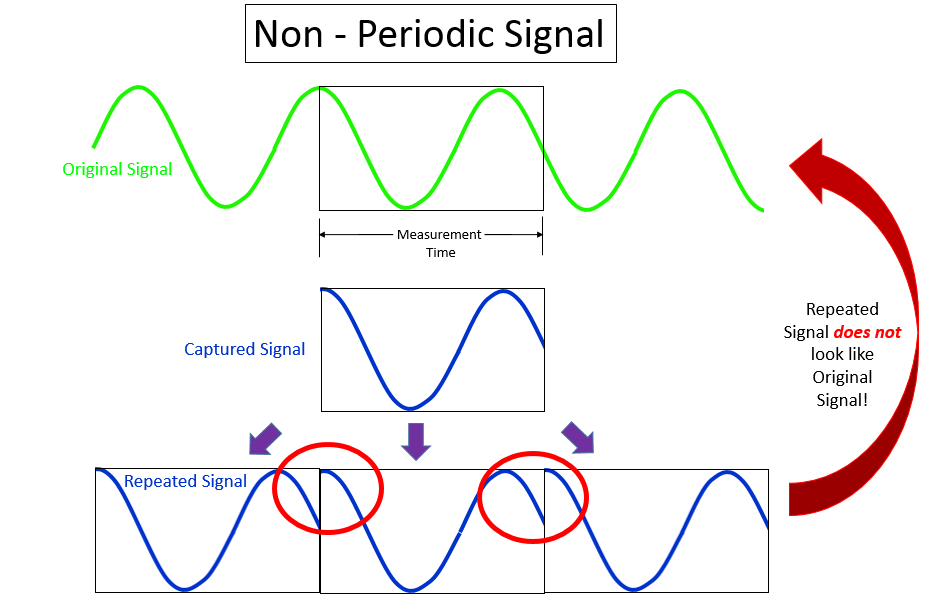

To reduce leakage, a mathematical function called a window is applied to the data. Windows are designed to reduce the sharp transient in the re-created signal as much as possible.

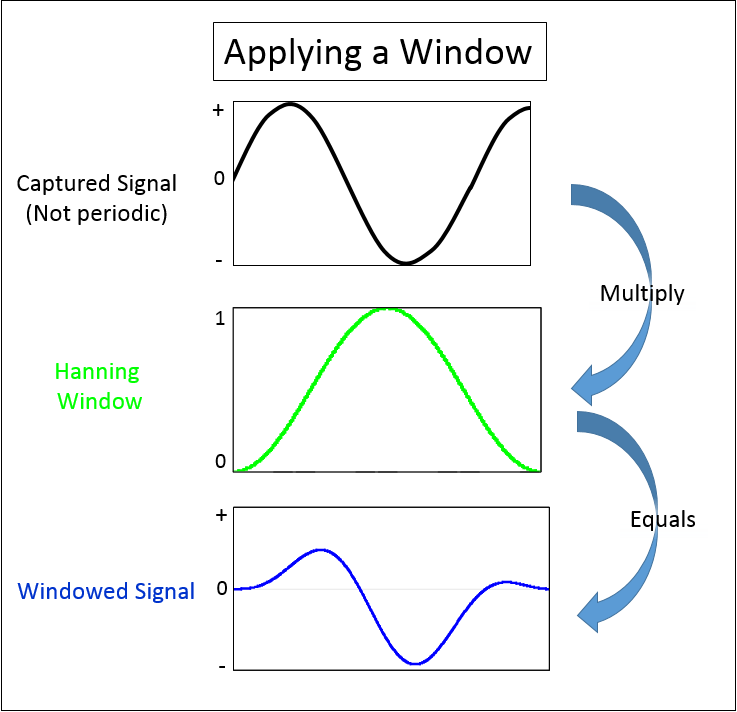

The main benefit of windowing is that the leakage is now confined over a smaller frequency range, instead of affecting the entire frequency bandwidth of the measurement.

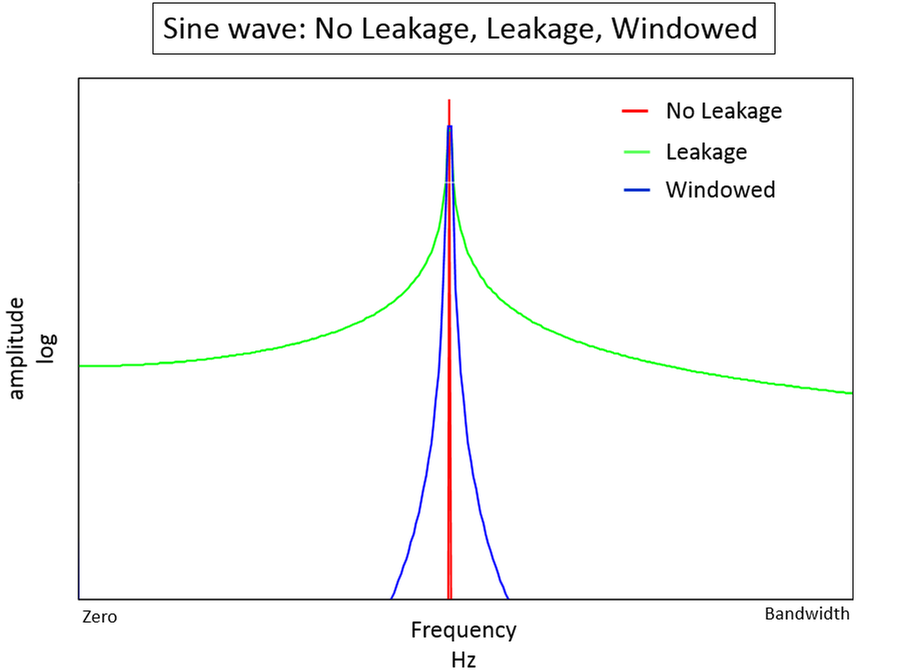

### Periodogram

A periodogram is a method for estimating the Power Spectrum Density of a random signal from a finite set of $N$ observations given by:

        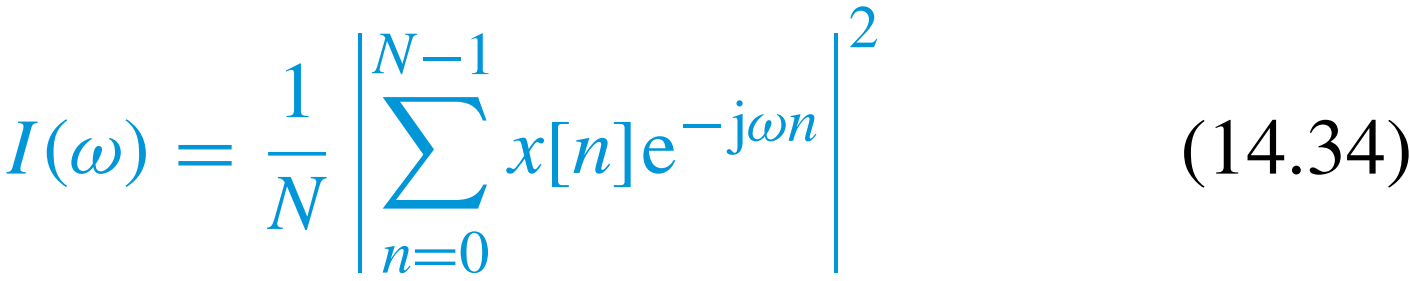

The periodogram uses a rectangular window $w\left(n\right)=1$.

#### Statistical Properties of the Periodogram

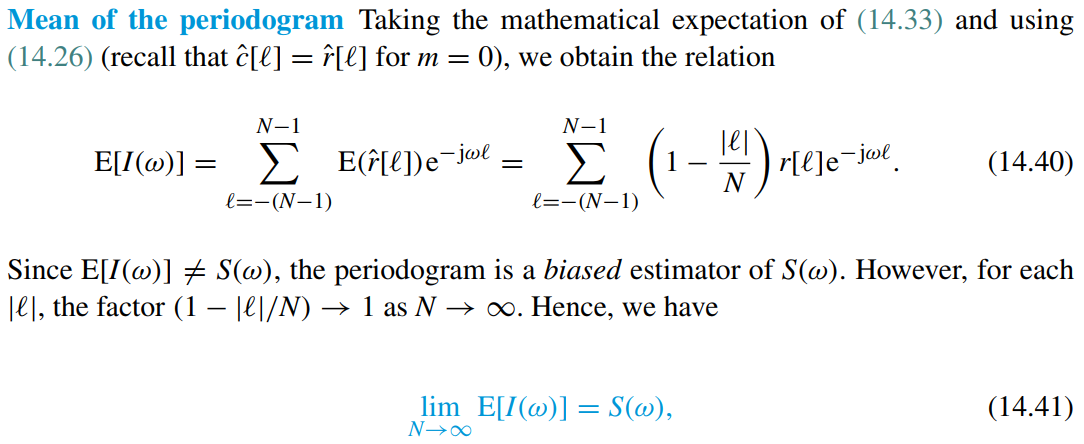

Eq. (14.41) says that as the window length $N$ increases towards infinity, the mean of the periodogram converges to the true power spectrum. Asymptotically (as $N$ increases) the periodogram is an unbiased estimator of $S\left(\omega \right)$.

For finite $N$, it has some bias which is reflected by the window function.

**Variance**

Under a variety of assumptions which holds for most random processes of practical interest, the variance of the periodogram estimator behaves like the square of the true PSD:

        

The main implication of (14.50) is that the **periodogram is not a good estimator of PSD** because, independently of $N$, the standard deviation of the estimator is as large as the quantity to be estimated.

In other words, the periodogram is not a consistent estimator; that is, its distribution does not tend to cluster more closely around the true PSD as $N$ increases.

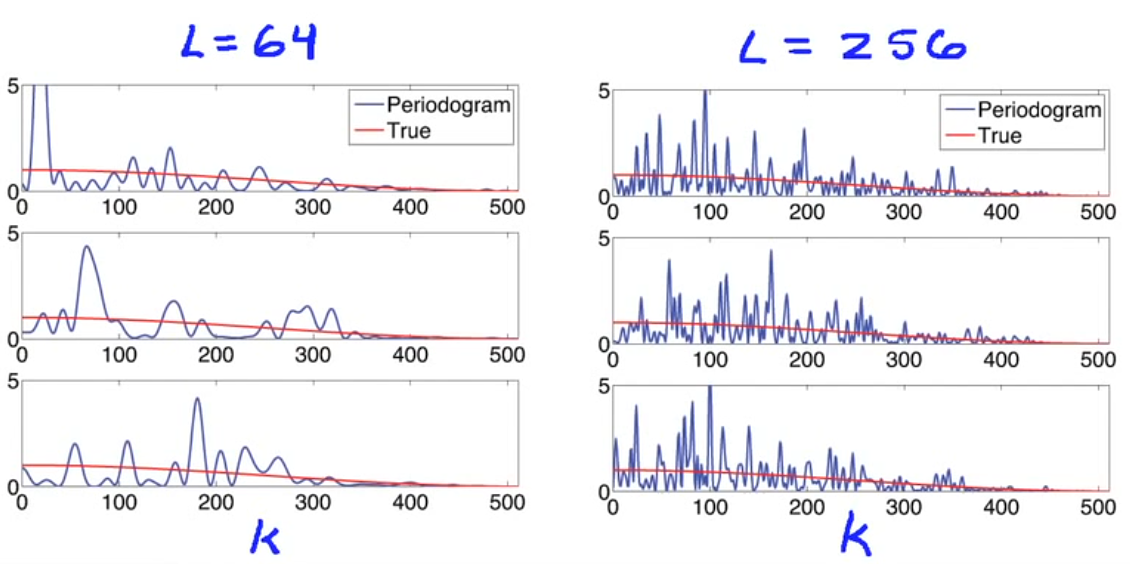

Note that the variance is high at lower frequencies where the true power spectrum is larger. As the true spectrum goes to zero, the variance gets smaller. This is in agreement with (14.50). If we get better resolution $L$ goes from 64 to $256$, the behaviour is still present. 

#### Covariance

The covariance between values of the periodogram at harmonically spaced frequencies is given by  

        

which states that closely spaced values of the periodogram are uncorrelated.  

### Modified Periodogram

The modified periodogram uses a window $w\left(n\right)$ that is not rectangular.

        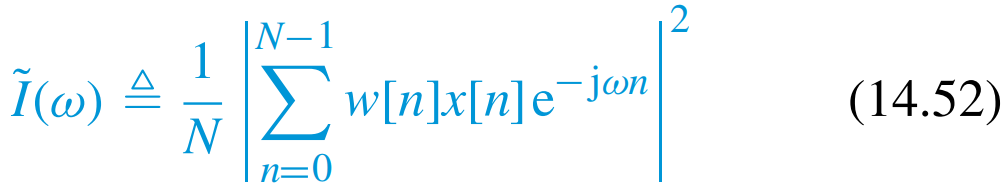

The normailisation factor has to be

        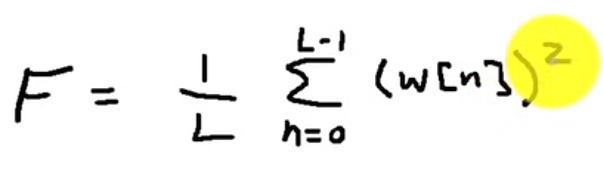

### Bartlett Window

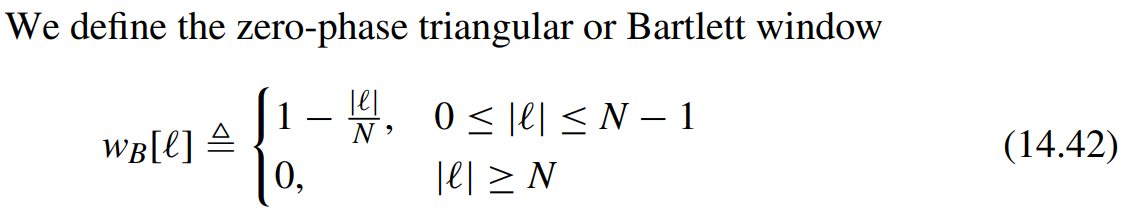

w = bartlett(64);
plot(w)
F = fft(w);
plot(abs(fft(w)))

## Welch's method

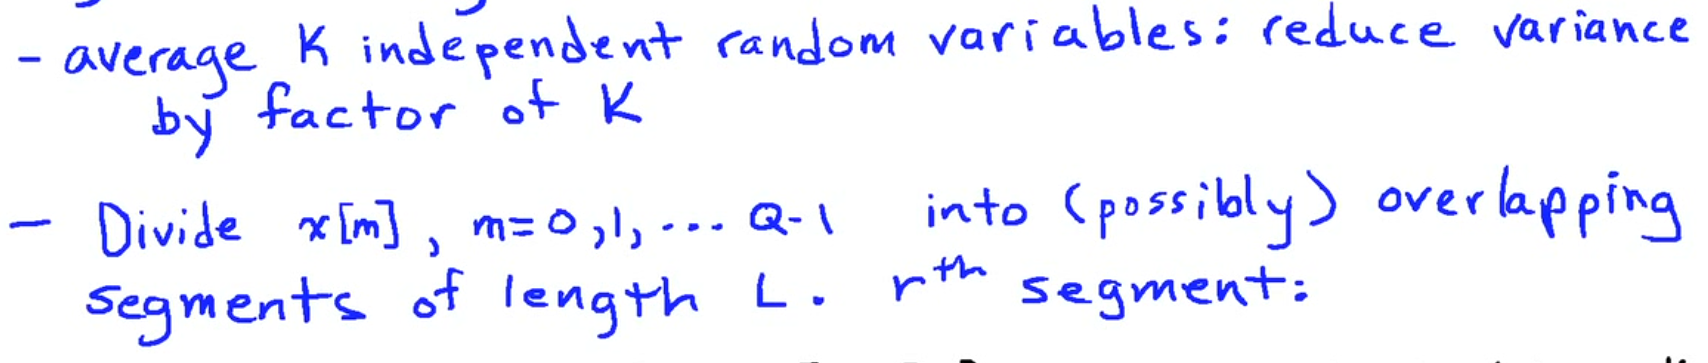

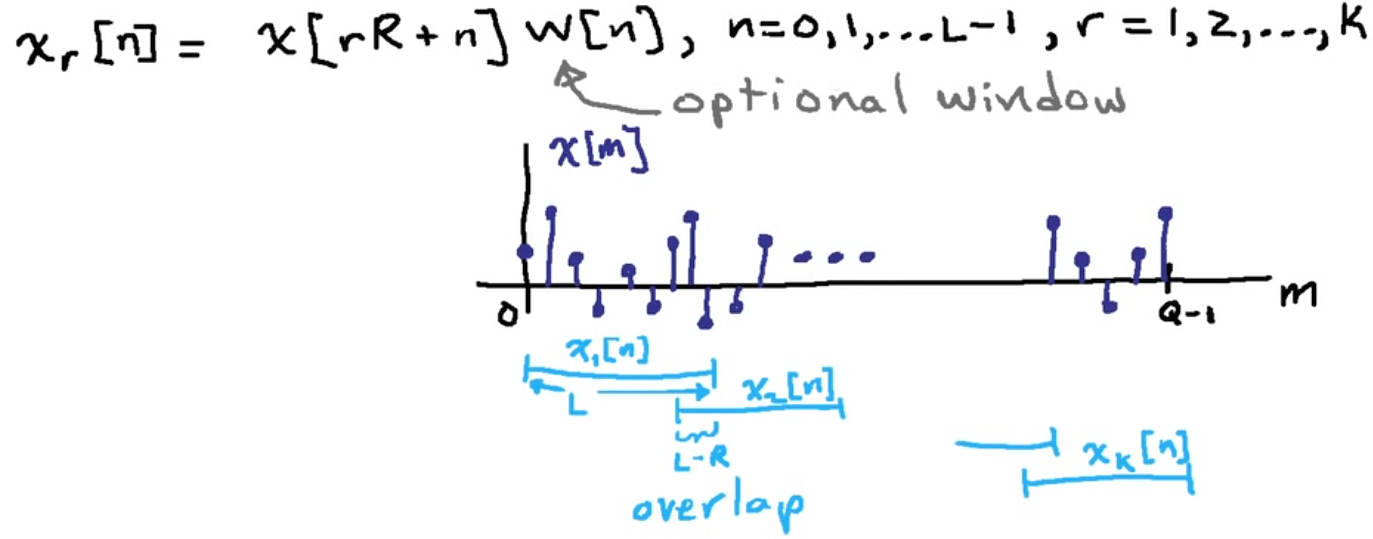 

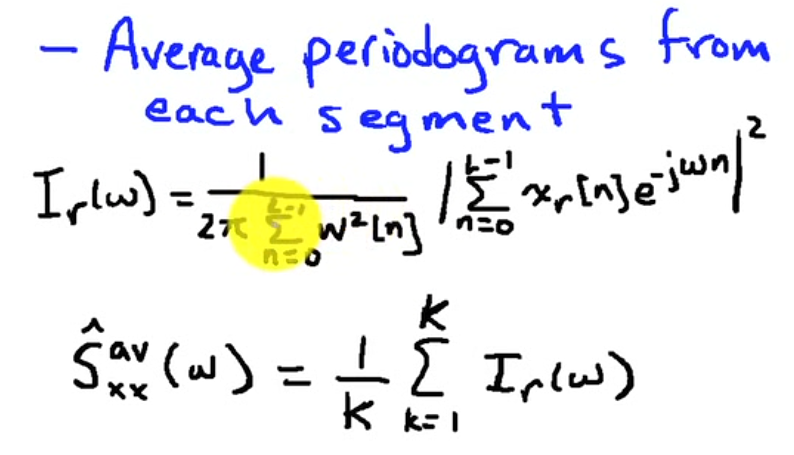

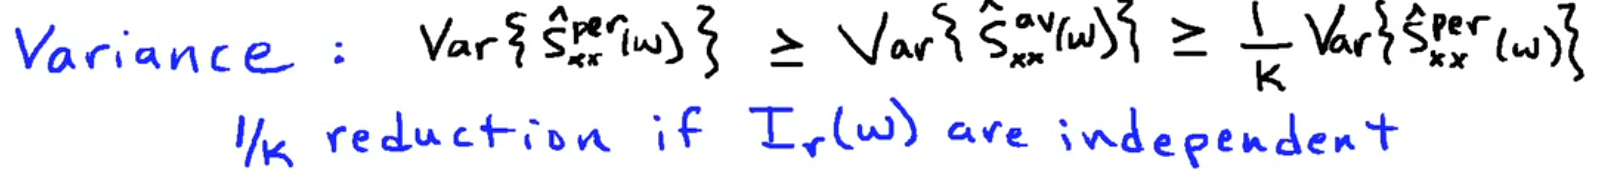

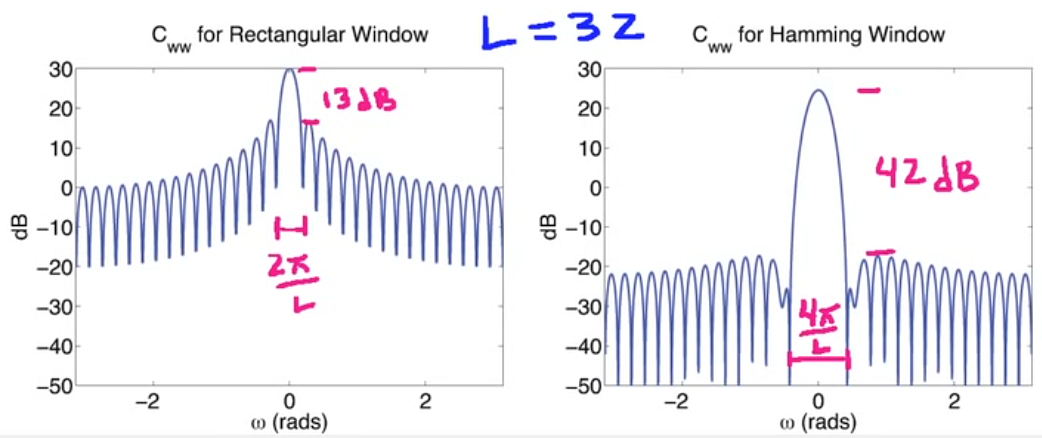

The nature of bias depends on the chosen window. There is a trade-off between main lobe width and side-lobe height. 

- Rectangular window gives you the narrowest main lobe but a fairly large side-lobe height. 

- Hamming window gives you twice the main lobe width but the side-lobes are much lower.

Hamming window sacrifies some resolution for increased dynamic range.

Dynamic range is the ratio of the largest signal amplitute and the smallest signal amplitude. How well can we realible distintinguish the largest from the smallest.

Windows are used to manage bias. 

Typically, we will trade resolution (main-lobe width) for dynamic range (side-lobe height)

## Functions

function r=acrs(x, L)
    % Computes the ACRS r[m] for 0<= m <= L
    % r=acrs(x-mean(x),L) yields the ACVS
    N=length(x);
    x1=zeros(N+L-1,1);
    x2=x1;
    x1(1:N,1)=x;
    for m=1:L
        x2=zeros(N+L-1,1);
        x2(m:N+m-1,1)=x;
        r(m)=x1'*x2;
    end
    r=r(:)/N;
end

function I=psdper(x, K)
    % Compute periodogram I(ω) using the FFT.
    % K-point FFT >= N
    N=length(x);
    X=fft(x,K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function r=acrsfft(x, L)
    % Computate the autocorrelation sequence using the FFT.
    % r=acrsfft(x-mean(x),L) yields the ACVS
    N=length(x);
    Q=nextpow2(N+L);
    X=fft(x,2^Q);
    r0=real(ifft(X.*conj(X)));
    r=r0(1:L)/N;
end

function I=psdmodper(x, K)
    % Compute the modified periodogram PSD estimate.
    % K-point FFT >= N
    N=length(x);
    w=hann(N); % choose window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    X=fft(x(:).*w(:),K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function psdbt(x, L, K)
    % Computate the Blackman–Tukey PSD estimate.
    % Blackman–Tukey PSD estimator of S(2*pi*k/K)
    N=length(x);
    w=hann(N); % Data window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    x=x.*w; % Data windowing
    r=acrsfft(x,L);
    wc=parzenwin(2*L-1); % Lag window
    rw=r.*wc(L:2*L-1); % Lag windowing
    g=zeros(K,1);
    g(1:L)=rw;
    g(K-L+2:K)=flipud(rw(2:L));
    G=fft(g,K); % f even => F real
    S=2*real(G(1:K/2)); S(1)=S(2);
end

function S=psdwelch(x, L, K)
    % Compute the Welch PSD estimate.
    % Welch PSD estimator of S(2*pi*k/K)
    M=fix((length(x)-L/2)/(L/2)) % 50% overlap
    time=(1:L)';
    I=zeros(K,1);
    w=hanning(L); % Choose window
    w=w/(norm(w)/sqrt(L)); % sum wˆ2[k]=L
    for m=1:M
    %xw=w.*detrend(x(time)); % detrenting
    xw=w.*x(time); % data windowing
    X=fft(xw,K);
    I=I+X.*conj(X);
    time=time+L/2;
    end
    I=I/(M*L); S=2*I(1:K/2); S(1)=S(2);
end